# Modeling density of bird migration

This MATLAB livescript presents a spatio-temporal model of the nocturnal migration of birds over Europe based on measurement of weather radars. 

The model decomposes a power transform of the bird density $Z$ [bird/km^2] at location$\mathit{\mathbf{s}}$ and time $t$ into

${\mathrm{Z}\left(t,\mathit{\mathbf{s}}\right)}^p =\tau \left(\mathit{\mathbf{s}}\right)+A\left(t,\mathit{\mathbf{s}}\right)+\gamma \left(t,\mathbf{s}\right)+R\left(t,\mathit{\mathbf{s}}\right)$,

where $\tau \left(s\right)$ is the spatial trend (fix in time), $A\left(t,\mathit{\mathbf{s}}\right)$ is the nighly amplitude (i.e. the average density over the night), $\gamma \left(t,\mathbf{s}\right)$ is a parametric curve modeling the varation of bird within the night and $R\left(t,\mathit{\mathbf{s}}\right)$ is the the intra-night fluctuation of migration. 

The model is decomposed at two scales.  and the second intra-nocturnal. 

- (section 3) The first at the nighly (or daily), where the average density over night is model with a Gaussian process. The spatial trend $\tau \left(s\right)$ is first accounted for with a deterministic planar function and then, the amplitude $A\left(t,\mathit{\mathbf{s}}\right)$ is model with a spatio-temporal covariance function.

- (section 4) The second scale is the intra-night fluctuation. First, the curve $\gamma \left(t,\mathbf{s}\right)$ is fitted to acount for the nightly trend (increase of bird density at the begining and descrease at the end of the night). Because of the variation of night duration with latitiude, longitude and time, the time of the curve is normalized according to local sunset (NNT=-1) and sunrise (NNT=1). Finally, a spatio-temporal random variable called residual $R\left(t,\mathit{\mathbf{s}}\right)$ is modeled with a covariance function. In addition, a non-stationary variance in used along the night for the residual. 

## 1. Import and create data

clear all; load('../1-Cleaning/data/dc_corr.mat'); addpath('./functions/'); warning('off')

Convert the volumetric densities to a surface densisties and compute the normalized night time (`NNT`)

for i_d=1:numel(dc)
    tmp=diff(double([0 max(0, (1:dc(i_d).levels).*dc(i_d).interval - dc(i_d).height )]))/1000;
    dc(i_d).denss = dc(i_d).dens*tmp';
    dc(i_d).NNT = datenum(dc(i_d).time'-mean([dc(i_d).sunrise;dc(i_d).sunset])) ./ datenum(dc(i_d).sunrise-dc(i_d).sunset)*2;
end

Define a few useful variable

uniqueDate = round(datenum(datetime(start_date:end_date)))';
dclat = [dc.lat]';
dclon = [dc.lon]';

Create the data structure `data` used for the rest of the code

dens_lim = 0.002;
data=[];
t15min = bsxfun(@plus,datenum(start_date:1/24/60*15:end_date),(-4:4)'*1/24/60);
t15min = datetime(sort(t15min(:)),'ConvertFrom','datenum');

for i_d=1:numel(dc)
    id = dc(i_d).NNT(:)>=-1 & dc(i_d).NNT(:)<=1 & dc(i_d).denss>dens_lim & ismember(dc(i_d).time,t15min);
    d=table();
    d.dens=dc(i_d).denss(id);
    d.NNT = dc(i_d).NNT(id)';
    d.radar=i_d*ones(sum(id),1);
    d.lat=dc(i_d).lat*ones(sum(id),1);
    d.lon=dc(i_d).lon*ones(sum(id),1);
    d.time = datenum(dc(i_d).time(id));
    d.duration = dc(i_d).etime(id)-dc(i_d).stime(id);
    [~,d.day]=ismember(round(datenum(dc(i_d).sunrise(id)))',uniqueDate);
    d.dayradar = sub2ind([numel(dc) numel(uniqueDate)],d.radar, d.day);
    % filter by day with less than 10% of data present
    tmp3 = [uniqueDate,histc(uniqueDate(d.day),uniqueDate)];
    tmp4 = ~ismember(uniqueDate(d.day),tmp3(0.1*max(tmp3(:,2))>tmp3(:,2),1));
    data = [data ; d(tmp4,:) ];
end

Define the covaraince function used

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

Delete variable not used

clear d dens_lim tmp* id

## 2. Power transformation $p$

Bird densities present a very skew histogram

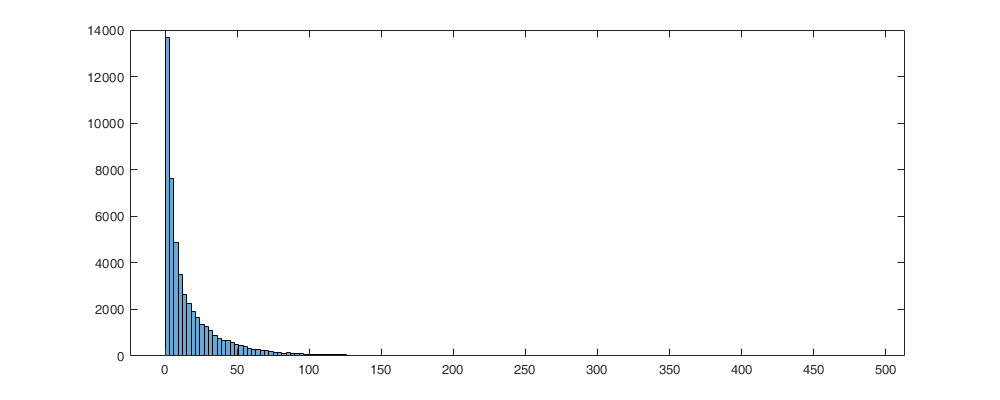

figure('position',[0 0 1000 400]); histogram(data.dens)

We fit a power transformation $p$ on $\mathrm{Z}\left(t,\mathit{\mathbf{s}}\right)$ by minimizing the [Kolmogorov-Smirnov test](https://en.wikipedia.org/wiki/Kolmogorov%E2%80%93Smirnov_test) of the transformed variable ${\mathrm{Z}\left(t,\mathit{\mathbf{s}}\right)}^p$

tmp = @(data,parm) data.^parm;
pow_a = fminsearch(@(parm) kstestmin(data.dens,tmp,parm), 1/8);
disp(['Power transformation p: ' num2str(pow_a)]);

Power transformation p: 0.13271


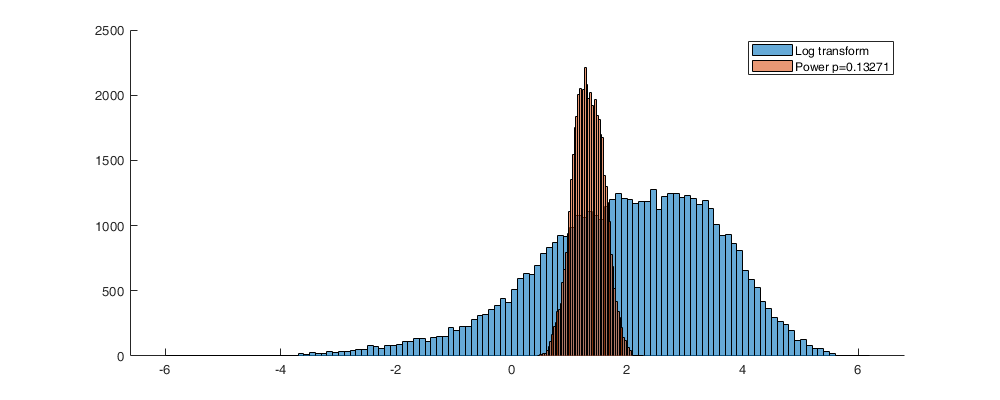


figure('position',[0 0 1000 400]); hold on;
histogram(log(data.dens))
histogram(data.dens.^pow_a)
legend('Log transform',['Power p=' num2str(pow_a)])

The transformed densities will be modeled

data.denst = data.dens.^pow_a;

## 3. Nighly amplitude

The first scale of the model is nightly (or daily), where the average bird density over night (called amplitude) is modeled as a Gaussian process with a spatial trend. Only the latitude component is fitted as adding the latitude shows little improvment. 


$$\tau \left(s\right)+A\left(t,\mathbf{s}\right)=w_0 +w_{\textrm{lat}} s_{\textrm{lat}} +A\left(t,\mathbf{s}\right)$$


Define the structure of amplitude, day * radar:

ampli.t = uniqueDate;
ampli.r = 1:69;
[ampli.T,ampli.R]=meshgrid(ampli.t,ampli.r);

Compute the amplitude as the average of  each radar-night

ampli.A=nan(numel(dc), numel(uniqueDate));
for i_d=1:numel(ampli.A)
    ampli.A(i_d)=mean(data.denst(data.dayradar==i_d));
end
ampli.isnan=isnan(ampli.A);

### 3.1 Spatial trend $\tau \left(s\right)$

Compute the parameters of the trend

ampli.w = [ones(sum(~ampli.isnan(:)),1) dclat(ampli.R(~ampli.isnan))] \ ampli.A(~ampli.isnan);
fprintf('Spatial trend parameters w_0=%.3f, w_{lat}=%.3f',ampli.w(1),ampli.w(2));

Spatial trend parameters w_0=2.566, w_{lat}=-0.024

Illustration of the spatial trend

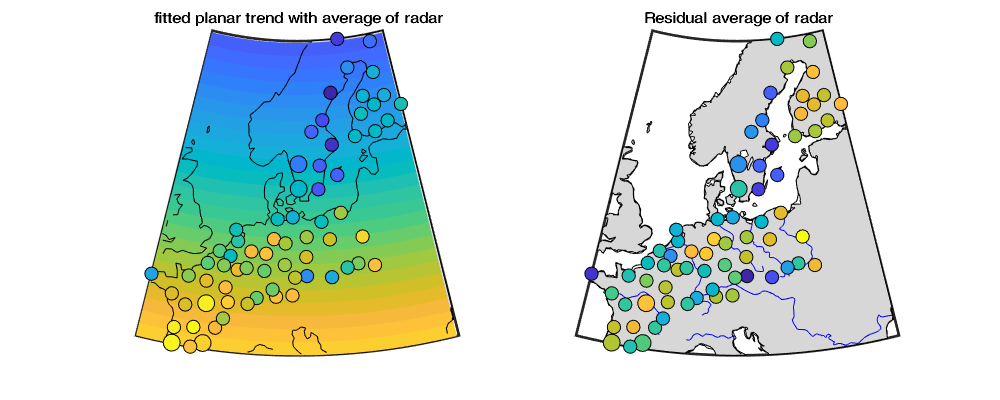

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
[LAT,LON] = meshgrid(min(dclat):max(dclat),min(dclon):max(dclon));
surfm(LAT,LON,LAT*ampli.w(2)+ampli.w(1))
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,nanmean(ampli.A,2),'filled','MarkerEdgeColor','k'); title('fitted planar trend with average of radar'); 

subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,[dc.maxrange]*4,nanmean(ampli.A,2)-dclat*ampli.w(2)-ampli.w(1),'filled','MarkerEdgeColor','k'); title('Residual average of radar');

The average of each radar during the study period shows a strong NS increase. The residual shows more the coridor of migration with lower migration density along the FR-NL coast, and along the Alps. Another strange effect is the drastic change between Sweden and Finland. 

Compute the de-trended amplitude

ampli.An = (ampli.A(~ampli.isnan)-dclat(ampli.R(~ampli.isnan))*ampli.w(2)-ampli.w(1));

Check histogram

%figure('position',[0 0 1000 400]); hold on;  histogram(ampli.An); histogram(ampli.A);

### 3.2 Covariance function of$A\left(t,\mathbf{s}\right)$

Buliding the distance matrix in time and space of the amplitude

Dtime=squareform(pdist(ampli.T(~ampli.isnan)));
Ddist=squareform(pdist([dclat(ampli.R(~ampli.isnan)) dclon(ampli.R(~ampli.isnan))],@lldistkm));

Compute the empirical covariance on a grid

ampli.cov.emp = bsxfun(@times, ampli.An', ampli.An);

ampli.cov.d=[0 1 300 500 1000];
ampli.cov.t=[0 1 2 3 5 10]; 
[ampli.cov.D,ampli.cov.T] = meshgrid(ampli.cov.d(1:end-1)+diff(ampli.cov.d)/2,ampli.cov.t(1:end-1));
ampli.cov.D_emp=nan(size(ampli.cov.D)); ampli.cov.T_emp = ampli.cov.D_emp; 
ampli.cov.emp_grid=nan(size(ampli.cov.D));
for i_t=1:numel(ampli.cov.t)-1
    for i_d=1:numel(ampli.cov.d)-1
        id = Dtime>=ampli.cov.t(i_t) & Dtime<ampli.cov.t(i_t+1) & Ddist>=ampli.cov.d(i_d) & Ddist<ampli.cov.d(i_d+1);
        ampli.cov.D_emp(i_t,i_d) = nanmean(Ddist(id)); ampli.cov.T_emp(i_t,i_d) = nanmean(Dtime(id));
        ampli.cov.emp_grid(i_t,i_d) = nanmean( ampli.cov.emp(id) );
    end
end
%figure;surf(ampli.cov.D_emp,ampli.cov.T_emp,ampli.cov.emp_grid); xlabel('Distance [km]'); ylabel('Time [days]')

The covariance function is fitted with a nugget and a Gneiting model. The data are filtered by a maximum distance and time in order to reduce the computational cost and overfitting long-distance/time lag. 

Gneiting_fit = @(parm) parm(1)*(ampli.cov.D_emp==0 & ampli.cov.T_emp==0) + parm(2)*(ampli.cov.D_emp==0) + parm(3).*Gneiting(ampli.cov.D_emp,ampli.cov.T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));

ampli.cov.parm0 =[.5 .5 .5 500 5 .5 .5 .5 ];
ampli.cov.parm_min=[0 0 0 0.0001 0 0 0 0 ]';
ampli.cov.parm_max=[nancov(ampli.An) nancov(ampli.An) nancov(ampli.An) 3000 10 1 1 1 ]';

rmse = @(parm) sum(sum(  ( 1000*abs(ampli.cov.emp_grid).*abs(Gneiting_fit(parm) - ampli.cov.emp_grid) ) ));
ampli.cov.parm = fmincon(rmse,ampli.cov.parm0,[],[],[1 1 1 0 0 0 0 0],nancov(ampli.An),ampli.cov.parm_min,ampli.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Construct the covariance function as inline function. Note that because `beta=0` (`parm(7)`), we can simplify the function:

% ampli.cov.C = @(D,T) ampli.cov.parm(1)*(D==0 & T==0) + ampli.cov.parm(2)*(D==0) + ampli.cov.parm(3)./( (T./ampli.cov.parm(5)).^(2.*ampli.cov.parm(6)) +1 ) .* exp(-(D./ampli.cov.parm(4)).^(2.*ampli.cov.parm(7)) );
ampli.cov.C = @(D,T) ampli.cov.parm(1)*(D==0 & T==0) + ampli.cov.parm(2)*(D==0) + ampli.cov.parm(3).*Gneiting(D,T,ampli.cov.parm(4),ampli.cov.parm(5),ampli.cov.parm(6),ampli.cov.parm(7),ampli.cov.parm(8));

Shows the resultings paramters

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],ampli.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.001		 0.006		 0.032	 500.023		 1.124			 0.979			 0.708			 0.095

Illustration of the fitted covariance function

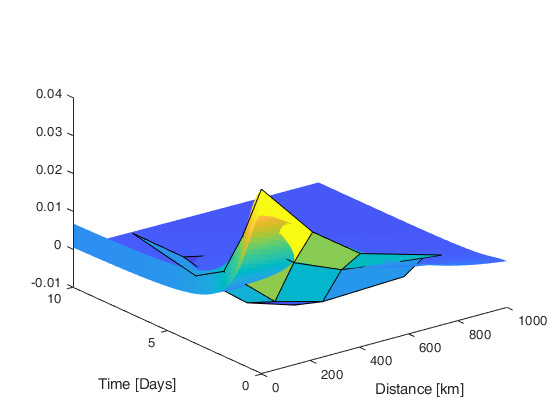

[tmpD,tmpT] = meshgrid(ampli.cov.d(1):1:ampli.cov.d(end),ampli.cov.t(1):0.1:ampli.cov.t(end));
figure; hold on;
s=surf(tmpD,tmpT,ampli.cov.C(tmpD, tmpT));
surf(ampli.cov.D_emp,ampli.cov.T_emp,ampli.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 4. Intra-night residual

The second scale is the intra-night. 

Compute the the residual (still containing the curve)

res.R = data.denst-ampli.A(data.dayradar);

### 4.1 Curve $\gamma \left(t,\mathbf{s}\right)$

A polynomial function is fitted on the curve 

res.apo=8;
res.a = bsxfun(@power,data.NNT,0:res.apo)\res.R;
disp('Polynomial coefficient a: ');fprintf('%.2f, ',res.a)

Polynomial coefficient a: 
0.04, -0.10, 0.07, 0.27, -1.29, -0.59, 2.86, 0.44, -1.92, 

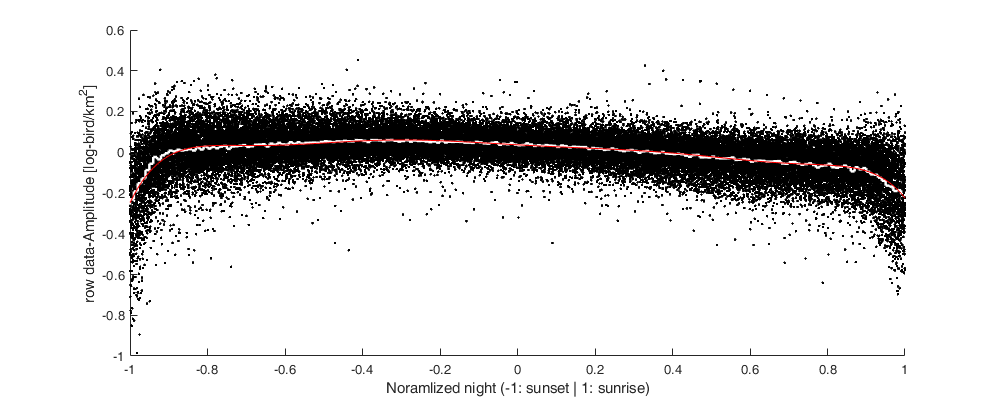


NNT_axis=-1:.01:1;
[~,id] = min(bsxfun(@minus,data.NNT,NNT_axis).^2,[],2);
figure('position',[0 0 1000 400]); hold on; 
plot(data.NNT,res.R,'.k');
stairs(NNT_axis-diff(NNT_axis(1:2)),splitapply(@nanmean,res.R,id),'w','linewidth',2)
plot(NNT_axis, bsxfun(@power,NNT_axis',0:res.apo)*res.a,'-r');  
xlabel('Normalized Night Time (NNT) (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [log-bird/km^2]'); ylim([-1 .6]); xlim([-1 1])

In addition, because of the transformation and the curve removal, the residual without curve contains a non-stationarity variable (see figure below). We fit another polynomial function to normalized thevariance of the residual along the night

res.bpo=10;
res.b = bsxfun(@power,data.NNT,0:res.bpo) \ (res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a).^2;
disp('Polynomial coefficient b');fprintf('%.2f, ',res.b)

Polynomial coefficient b
0.00, -0.00, 0.02, 0.04, -0.17, -0.17, 0.62, 0.26, -0.93, -0.12, 0.49, 

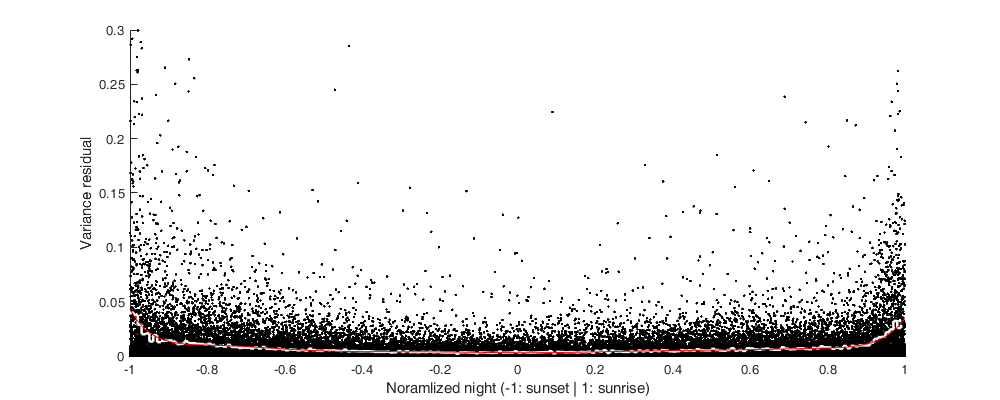


figure('position',[0 0 1000 400]); hold on;
plot(data.NNT,(res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a).^2,'.k');
stairs(NNT_axis-diff(NNT_axis(1:2)),splitapply(@nanmean,(res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a).^2,id),'w','linewidth',2)
plot(NNT_axis, bsxfun(@power,NNT_axis',0:res.bpo)*res.b,'-r');
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('Variance residual');ylim([0 .3]); xlim([-1 1])

Finally, combining the polynomial of the curve and the correction for variance, we find the de-trended residual wihich is modeled in the next section:

res.Rn = (res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a) ./ sqrt(bsxfun(@power,data.NNT,0:res.bpo)*res.b);

Check the histogram

% figure('position',[0 0 1000 400]); histogram(res.Rn);xlim([-6 6])

### 4.2 Covariance function of $R\left(t,\mathit{\mathbf{s}}\right)$

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table(); 
for i_t=1:numel(ampli.t)
    id = find(data.day==i_t);
    d= table();
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    A = ones(numel(id));
    B = tril(A);
    D=[D ; d(B(:)==1,:)];
end

Empirical covariance function

res.cov.d=[0 1 100 150 200 250 300 600 1000];
res.cov.t=[0 .01 .02 .05 .07 .1 .5]; 
[res.cov.D,res.cov.T]=meshgrid(res.cov.d(1:end-1)+diff(res.cov.d)/2,res.cov.t(1:end-1)+diff(res.cov.t)/2);
res.cov.D_emp=nan(size(res.cov.D)); res.cov.T_emp=nan(size(res.cov.D));
res.cov.emp_grid=nan(size(res.cov.D));

for i_d=1:numel(res.cov.d)-1
    id1 = find(D.Ddist>=res.cov.d(i_d) & D.Ddist<res.cov.d(i_d+1));
    for i_t=1:numel(res.cov.t)-1
        id2 = id1(D.Dtime(id1)>=res.cov.t(i_t) & D.Dtime(id1)<res.cov.t(i_t+1));
        res.cov.emp_grid(i_t,i_d)= mean(res.Rn(D.Did1(id2)) .* res.Rn(D.Did2(id2)));
        res.cov.D_emp(i_t,i_d) = nanmean(D.Ddist(id2)); 
        res.cov.T_emp(i_t,i_d) = nanmean(D.Dtime(id2));
    end
end

Figure

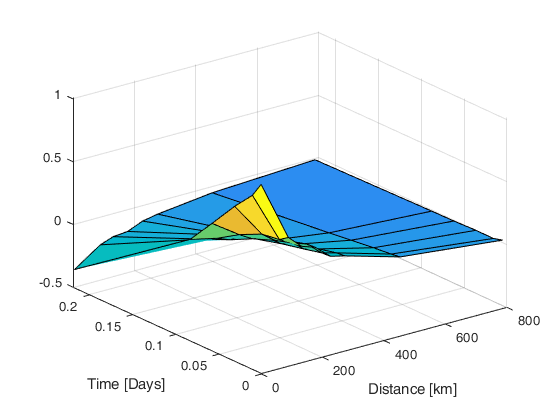

figure; surf(res.cov.D_emp,res.cov.T_emp,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');

Calibrate the covariance function 

Gneiting_fit = @(parm) parm(1)*(res.cov.D_emp==0 & res.cov.T_emp==0) + parm(2)*(res.cov.D_emp==0) + parm(3).*Gneiting(res.cov.D_emp,res.cov.T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));

res.cov.parm0 =[.5 .5 .5 500 5 .5 .5 .5 ];
res.cov.parm_min=[0 0 0 0.0001 0 0 0 0 ]';
res.cov.parm_max=[nancov(res.Rn) nancov(res.Rn) nancov(res.Rn) 3000 10 1 1 1 ]';

rmse = @(parm) sum(sum(  ( 1000*abs(res.cov.emp_grid).*abs(Gneiting_fit(parm) - res.cov.emp_grid) ) ));
res.cov.parm = fmincon(rmse,res.cov.parm0,[],[],[1 1 1 0 0 0 0 0],[nancov(res.Rn)],res.cov.parm_min,res.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Build the inline covariance function. Note that because `beta=0` (`parm(7)`), we can simplify the function

res.cov.C = @(D,T) res.cov.parm(1)*(D==0 & T==0) + res.cov.parm(2)*(D==0) + res.cov.parm(3).*Gneiting(D,T,res.cov.parm(4),res.cov.parm(5),res.cov.parm(6),res.cov.parm(7),res.cov.parm(8));

Display the parameters values.

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],res.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.089		 0.000		 0.913	 190.394		 0.066			 0.999			 0.403			 0.997

Figure

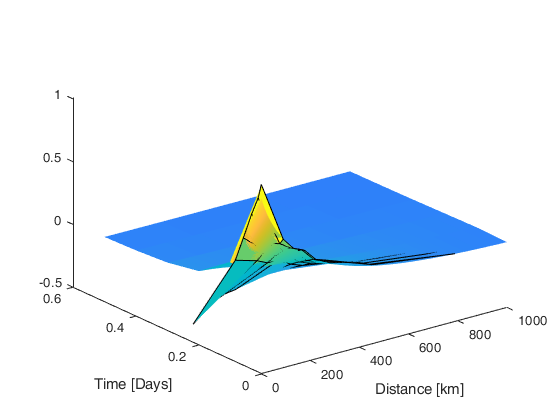

[tmpD,tmpT] = meshgrid(res.cov.d(1):1:res.cov.d(end),res.cov.t(1):0.1:res.cov.t(end));
figure; hold on;
s=surf(tmpD,tmpT,res.cov.C(tmpD,tmpT));
surf(res.cov.D_emp,res.cov.T_emp,res.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

The empirical variogram of the residu shows a very intersting effect.

[...] 

The empirical variogram of the absolute value of the residu confirms our explanation with the lowest variance.

## 5. Save

Save the parameters of the model. 

save('data/Density_inference.mat','data','ampli','res','pow_a','-v7.3')
% writetable(data,'data/Density_data.csv')

## 6. Model quality (bonus)

figure('position',[0 0 1000 400]); hold on; ylabel('Normalized Residual'); xlabel('Transformed density')
scatter(data.denst,res.Rn,'.k'); 
coeffs = [ones(size(data.denst)) data.denst] \ res.Rn;
plot( [.2 2.2],[1 .2;1 2.2]*coeffs,'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.2 2.2],[0 0],'r','LineWidth',2); axis([.4 2 -4 4])
figure('position',[0 0 1000 400]); hold on; ylabel('Residual'); xlabel('Amplitude')
scatter(ampli.A(data.dayradar),res.R,'.k'); 
coeffs = [ones(size(data.dayradar)) ampli.A(data.dayradar)] \ res.R;
plot( [.5 2],[.5 1;2 1]*coeffs,'--','Color',[.5 .5 .5],'LineWidth',2)
plot([.5 2],[0 0],'r','LineWidth',2);
for i_r=1:numel(dc)
    res_r_m(i_r)=mean(res.Rn(data.radar==i_r));
    res_r_std(i_r)=std(res.Rn(data.radar==i_r));
end
figure('position',[0 0 1000 400]);
subplot(1,2,1); hold on; worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,res_r_m,'filled','MarkerEdgeColor','k'); title('Average Residual'); colorbar;
subplot(1,2,2); hold on; worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
plotm(coastlat, coastlon,'k')
scatterm(dclat,dclon,[dc.maxrange]*4,res_r_std,'filled','MarkerEdgeColor','k'); title('Std residual'); colorbar;